clear

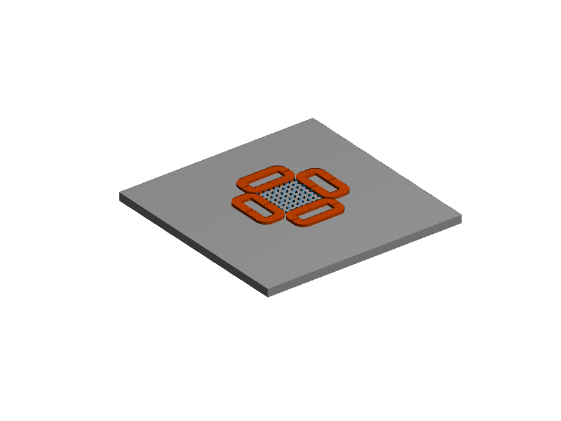

figure
hold on

Model = myModel;
comsolModel = mphopen(Model.comsol.coil_filename);
mphgeom(comsolModel, 'geom1', 'edgemode','off', 'facecolor',[0.9 0.3 0])

colors{1} = [0.7 0.7 0.7];

bottom_z = 0;
for k = 1:length(Model.layers)-1
    width = Model.comsol.truncate_width;
    thickness = Model.layers{k}.thickness;
    bottom_z = bottom_z - thickness;

    plot_block(0, 0, bottom_z+thickness/2, width, width, thickness, colors{k})
end

l = 1e-3;
for k = 1:size(Model.sensors.positions, 2)
    pos = Model.sensors.positions(:,k);
    plot_block(pos(1), pos(2), pos(3), l, l, l, 'k')
end

r = Model.sensors.positions;
v = Model.sensors.axes * l * 1.5;
quiver3(r(1,:), r(2,:), r(3,:), v(1,:), v(2,:), v(3,:), 'off')

title('')
axis off
camlight

function plot_block(cx,cy,cz, dx,dy,dz, color)

x = [-dx dx dx -dx -dx] / 2;
x = [x; x] + cx;
y = [-dy -dy dy dy -dy] / 2;
y = [y; y] + cy;
z = [dz; -dz] .* ones(1,5) / 2 + cz;

surf(x, y, z, 'FaceColor',color, 'EdgeColor','none')  
patch(x', y', z', color, 'EdgeColor','none')

end